# **MPC Tracking Init**

**Auteur: Randolf NKIMO LENOU**

Considérons le système suivant :


$$\left\lbrace \begin{array}{ll}
x\left(t+1\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right) & \\
y\left(t\right)=\textrm{Cx}\left(t\right) & 
\end{array}\right.$$


l'objectif est de faire suivre à la sortie une reference (tracking), pour cela nous avons besoin de formuler le problème en utilisant une entrée incrementée


$$\begin{array}{l}
x\left(t+1\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)\pm \textrm{Bu}\left(t-1\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=Ax\left(t\right)+\textrm{Bu}\left(t-1\right)+B\left(u\left(t\right)-u\left(t-1\right)\right)\;\;\textrm{avec}\;\;x_u \left(t\right)=u\left(t-1\right)\;\textrm{et}\;\Delta u\left(t\right)=u\left(t\right)-u\left(t-1\right)\\
x\left(t+1\right)=\textrm{Ax}\left(t\right)+Bx_u \left(t\right)+B\Delta u\left(t\right)\\
D^{\prime } \textrm{un}\;\textrm{autre}\;\textrm{coté}:\\
x_u \left(t+1\right)=u\left(t\right)=\Delta u\left(t\right)+x_u \left(t\right)\\
\textrm{Considérons}\;\textrm{le}\;\textrm{système}\;\textrm{augmenté}\;\textrm{avec}\;\textrm{pour}\;\textrm{entrée}\;\Delta u\left(t\right)\;\textrm{et}\;\textrm{pour}\;\textrm{état}\;X_a =\left\lbrack \begin{array}{c}
x\left(t\right)\\
x_u \left(t\right)
\end{array}\right\rbrack \\
\left\lbrace \begin{array}{ll}
X_a \left(t+1\right)=\left\lbrack \begin{array}{cc}
A & B\\
0 & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
x_u \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\\
I
\end{array}\right\rbrack  & \Delta u\left(t\right)\\
y\left(t\right)=\left\lbrack \begin{array}{cc}
C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
x_u \left(t\right)
\end{array}\right\rbrack  & 
\end{array}\right.\\
\left\lbrace \begin{array}{ll}
X_a \left(t+1\right)={\mathrm{A}}_a X_a \left(t\right)+B_a \Delta u\left(t\right) & \\
y\left(t\right)=C_a X_a \left(t\right) & 
\end{array}\right.
\end{array}$$


Le problème de tracking optimal est formulé comme suit :


$$\min_{\Delta u_{0\;} ,\ldotp \ldotp \ldotp ,\;\Delta u_{N-1} }$$
 
$$\sum_{k=0}^{N-1} {\left(y_{k+1} -r_0 \right)}^T Q\left(y_{k+1} -r_0 \right)+{{\Delta u}_k }^T R$$

$${\Delta u}_k$$



$$s\ldotp t\;\left\lbrace \begin{array}{ll}
u_{\min } \le u_k \le u_{\max }  & \\
y_{\min } \le y_k \le y_{\max }  & \textrm{and}\;{\;\Delta u}_{\min } \le {\Delta u}_k \le {\Delta u}_{\max } 
\end{array}\right.$$



$$\textrm{Posons}\;Z={\left\lbrack \begin{array}{ccccc}
{\;\Delta u}_0  & {\;\Delta u}_1  & \;\;\ldotp \ldotp \ldotp  &  & {\;\Delta u}_{N-1} 
\end{array}\right\rbrack }^T \;\textrm{et}\;X={\left\lbrack \begin{array}{ccccc}
{\;X}_{\textrm{a1}}  & {\;X}_{\textrm{a2}}  & \;\;\ldotp \ldotp \ldotp  &  & {\;X}_{\textrm{aN}} 
\end{array}\right\rbrack }^T \;\;\textrm{et}\;r={\left\lbrack \begin{array}{ccccc}
{\;r}_0  & {\;r}_0  & \;\;\ldotp \ldotp \ldotp  &  & r_0 
\end{array}\right\rbrack }^T \;$$
 

Le problème de tracking devient:

 
$$\min_{\Delta u_{0\;} ,\ldotp \ldotp \ldotp ,\;\Delta u_{N-1} }$$
 
$$\sum_{k=0}^{N-1} {\left(C_a X_{a\_k+1} -r_0 \right)}^T Q\left(C_a X_{a\_k+1} -r_0 \right)+{{\Delta u}_k }^T R$$

$${\Delta u}_k$$


  
$$\min_{\Delta u_{0\;} ,\ldotp \ldotp \ldotp ,\;\Delta u_{N-1} }$$
 
$$\sum_{k=0}^{N-1} {X_{a\_k+1} }^T \;{{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}} }^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}} {\;\;X}_{a\_k+1} -2{r_0 }^T \mathit{\mathbf{Q}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}} {{{\;\;X}_{a\_k+1} +\;\Delta u}_k }^T \mathit{\mathbf{R}}$$

$${\Delta u}_k +{r_0 }^T \mathit{\mathbf{Q}}r_0$$
 

En mettant cette expression sous forme matricielle on obtient: *(ici le coût terminal ****S**** est nul)*


$$\min_{\Delta u_{0\;} ,\ldotp \ldotp \ldotp ,\;\Delta u_{N-1} }$$
 
$$\left\lbrack \begin{array}{ccccc}
{{\;X}_{\textrm{a1}} }^T  & {{\;X}_{\textrm{a2}} }^T  & \;\;\ldotp \ldotp \ldotp  &  & {{\;X}_{\textrm{aN}} }^T 
\end{array}\right\rbrack \underset{\bar{\mathit{\mathbf{Q}}} }{\underbrace{\left\lbrack \begin{array}{cccc}
{{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}} }^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}}  &  &  & \\
 & {{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}} }^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}}  &  & \\
 &  & {{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}} }^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}}  & \\
 &  &  & {{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}} }^{\mathit{\mathbf{T}}} \mathit{\mathbf{S}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}} 
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
{\;X}_{\textrm{a1}} \\
{\;X}_{\textrm{a2}} \\
\vdots \\
\\
{\;X}_{\textrm{aN}} 
\end{array}\right\rbrack -2\left\lbrack \begin{array}{ccccc}
{r_0 }^T  & {r_0 }^T  & \;\;\ldotp \ldotp \ldotp  &  & {r_0 }^T 
\end{array}\right\rbrack \underset{\bar{T} }{\underbrace{\left\lbrack \begin{array}{cccc}
\mathit{\mathbf{Q}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}}  &  &  & \\
 & \mathit{\mathbf{Q}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}}  &  & \\
 &  & \mathit{\mathbf{Q}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}}  & \\
 &  &  & \mathit{\mathbf{S}}{\mathit{\mathbf{C}}}_{\mathit{\mathbf{a}}} 
\end{array}\right\rbrack } }$$

$$\left\lbrack \begin{array}{c}
{\;X}_{\textrm{a1}} \\
{\;X}_{\textrm{a2}} \\
\\
\\
{\;X}_{\textrm{aN}} 
\end{array}\right\rbrack$$



$$+\left\lbrack \begin{array}{ccccc}
{{\;\Delta u}_0 }^T  & {{\;\Delta u}_1 }^T  & \;\;\ldotp \ldotp \ldotp  &  & {{\;\Delta u}_{N-1} }^T 
\end{array}\right\rbrack$$

$$\underset{\bar{\mathit{\mathbf{R}}} }{\underbrace{\left\lbrack \begin{array}{cccc}
\mathit{\mathbf{R}} &  &  & \\
 & \mathit{\mathbf{R}} &  & \\
 &  & \mathit{\mathbf{R}} & \\
 &  &  & \mathit{\mathbf{R}}
\end{array}\right\rbrack } }$$

$$\left\lbrack \begin{array}{c}
{\;\Delta u}_0 \\
{\;\Delta u}_1 \\
\\
\\
{\;\Delta u}_{N-1} 
\end{array}\right\rbrack$$


Donc : $\min_{\Delta u_{0\;} ,\ldotp \ldotp \ldotp ,\;\Delta u_{N-1} }$ $X^T \bar{\mathit{\mathbf{Q}}} X+Z^T \bar{\mathit{\mathbf{R}}} Z-2r^T \bar{\mathit{\mathbf{T}}} X\;\;\;\left(1\right)$ 

De plus la dynamique du système augmente peut se mettre sous la forme : 

$\left\lbrack \begin{array}{c}
{\;X}_{\textrm{a1}} \\
{\;X}_{\textrm{a2}} \\
\\
\\
{\;X}_{\textrm{aN}} 
\end{array}\right\rbrack$= $\underset{\bar{\mathit{\mathbf{S}}} }{\underbrace{\left\lbrack \begin{array}{cccc}
B_{\mathit{\mathbf{a}}}  &  &  & \\
{\mathit{\mathbf{A}}}_{\mathit{\mathbf{a}}} B_{\mathit{\mathbf{a}}}  & B_{\mathit{\mathbf{a}}}  &  & \\
\vdots  &  & B_{\mathit{\mathbf{a}}}  & \\
{{\mathit{\mathbf{A}}}_{\mathit{\mathbf{a}}} }^{\mathit{\mathbf{N}}-1} B_{\mathit{\mathbf{a}}}  &  &  & B_{\mathit{\mathbf{a}}} 
\end{array}\right\rbrack } }$$\left\lbrack \begin{array}{c}
{\;\Delta u}_0 \\
{\;\Delta u}_1 \\
\vdots \\
\\
{\;\Delta u}_{N-1} 
\end{array}\right\rbrack +$$\underset{\bar{\mathit{\mathbf{K}}} }{\underbrace{\left\lbrack \begin{array}{c}
{\mathit{\mathbf{A}}}_{\mathit{\mathbf{a}}} \\
{{\mathit{\mathbf{A}}}_{\mathit{\mathbf{a}}} }^2 \\
\\
\\
{{\mathit{\mathbf{A}}}_{\mathit{\mathbf{a}}} }^{\mathit{\mathbf{N}}} 
\end{array}\right\rbrack } }$${\;X}_{\textrm{a0}}$

Donc: $X=\bar{\mathit{\mathbf{S}}} Z+\bar{\mathit{\mathbf{K}}} {\;X}_{\textrm{a0}} \;\;\left(2\right)$

(2) dans (1) nous donne :


$$\min_{\Delta u_{0\;} ,\ldotp \ldotp \ldotp ,\;\Delta u_{N-1} }$$
 
$$Z^T \left({\bar{\mathit{\mathbf{S}}} \;}^{\mathit{\mathbf{T}}} \bar{\mathit{\mathbf{Q}}} \;\bar{\mathit{\mathbf{S}}} +\bar{\mathit{\mathbf{R}}} \right)Z+2\left\lbrack \begin{array}{cc}
{{\;X}_{\mathrm{a0}} }^T  & r^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\bar{\mathit{\mathbf{K}}} }^{\mathit{\mathbf{T}}} \;\bar{\mathit{\mathbf{Q}}} \;\bar{\mathit{\mathbf{S}}} \\
-\bar{\mathit{\mathbf{T}}} \;\bar{\mathit{\mathbf{S}}} 
\end{array}\right\rbrack Z$$


La contrainte sur $u_{\min } \le u_k \le u_{\max }$ peut s'exprimer en fonction de ${\Delta u}_k$ 

On sait que  $u_k$ = $u_{k-1} +{\Delta u}_k =X_{\textrm{ak}} \left(3\right)+{\Delta u}_k$

De (2), on peut trouver $X_{\textrm{ak}} \;\left(3\right)$en fonction de ${\Delta u}_k$ 

$X=\bar{\mathit{\mathbf{S}}} Z+\bar{\mathit{\mathbf{K}}} {\;X}_{\textrm{a0}} \Longrightarrow \underset{X_{\textrm{ak}} \left(3\right)}{\underbrace{\tilde{C} X} } =\tilde{C} \bar{\mathit{\mathbf{S}}} Z+\tilde{C} \bar{\mathit{\mathbf{K}}} {\;X}_{\textrm{a0}} \;$ avec $\tilde{C} =\left\lbrack \begin{array}{cccc}
c &  &  & \\
 & c &  & \\
 &  & c & \\
 &  &  & c
\end{array}\right\rbrack \;\textrm{avec}\;c=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack$

Ainsi la contrainte devient: $\left\lbrace \begin{array}{ll}
\;\;\;\left(\tilde{C} \bar{\mathit{\mathbf{S}}} +\textrm{eye}\left(N\right)\right)Z\le U_{\max } -\tilde{C} \bar{\mathit{\mathbf{K}}} {\;X}_{\textrm{a0}}  & \\
-\left(\tilde{C} \bar{\mathit{\mathbf{S}}} +\textrm{eye}\left(N\right)\right)Z\le {-U}_{\min } +\tilde{C} \bar{\mathit{\mathbf{K}}} {\;X}_{\textrm{a0}}  & 
\end{array}\right.$

close all
clear;
clc

## Paramètres du système de base et matrices de pondération avec Ts=1

A = [-1 0; 1 0];
B = [1;0];
C = [0,1];
D = 0;
x_0 = [8 -5]';

Ts = 1; 
N = 10;  

Q = 4; 
R = 1;

umax = 2;
umin =-2;

delta_umax = 1;
delta_umin =-1;

## Définition du système augmenté

A_ = [A B; zeros(1,2), eye(1)];
B_ = [B;eye(1)];
C_ = [C, zeros(1)];

## Calcul des différentes matrices pour la formalisation du problème

% %%% Calcul de Q_
P = C_'*zeros(1,1)*C_;
q = C_'*Q*C_;
sizeQ_ = [3*N-3, 3*N-3]; %
nb_Q = sizeQ_(1)/size(q, 1);
Q_ = blkdiag(kron(eye(nb_Q), q), P);
% %%% Fin Calcul Q_

% %% Calcul de T_
T_ = blkdiag(kron(eye(9), Q*C_), zeros(1,1)*C_);
% %% Fin Calcul T_

% %%% Calcul de R_
R_ = diag(repmat(R, 1, N));
% %%% Fin Calcul R_

% %%% Calcul de S_
S_ =[];
for i=1:N
 for j=1:N
    k = i-j;
 if k<0
    s(:,j) = zeros(3,1);
 else
    s(:,j) = A_^k*B_;
 end
 end
 S_ = [S_;s];
end
% %%% Fin Calcul S_

% %%% Calcul de K_
K_=[];
for i=1:N
K_ = [K_; A_^i];
end
% %%% Fin Calcul K_

%%%%%%%%%%%%%%%%%%%%%%
H = S_'*Q_*S_ + R_;
F = 2*[K_'*Q_*S_; -T_*S_]';
%%%%%%%%%%%%%%%%%%%%%%

% %%% Calcul de G
G = kron(eye(N),eye(1));
G = [G;kron(eye(N),-eye(1))];
% %%% FilnCalcul de G 

% %%% Calcul W et S
W = [delta_umax*ones(N,1);-delta_umin*ones(N,1)];
S = [zeros(2*N,3)];
% %%% FilnCalcul de W et S 

## Résultats

On a bien évidement la sortie qui suit la réference elle converge vers **6**

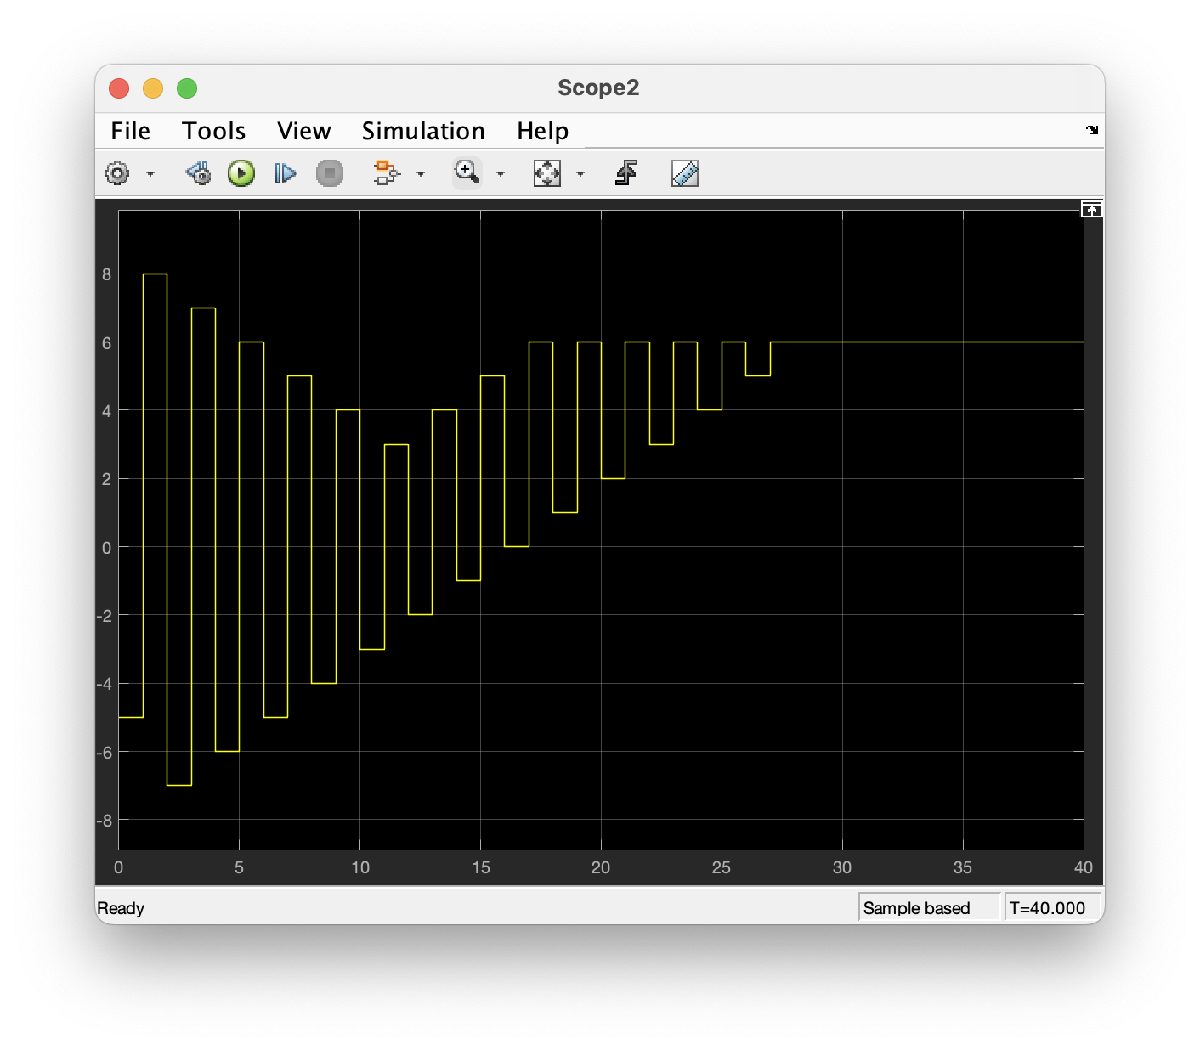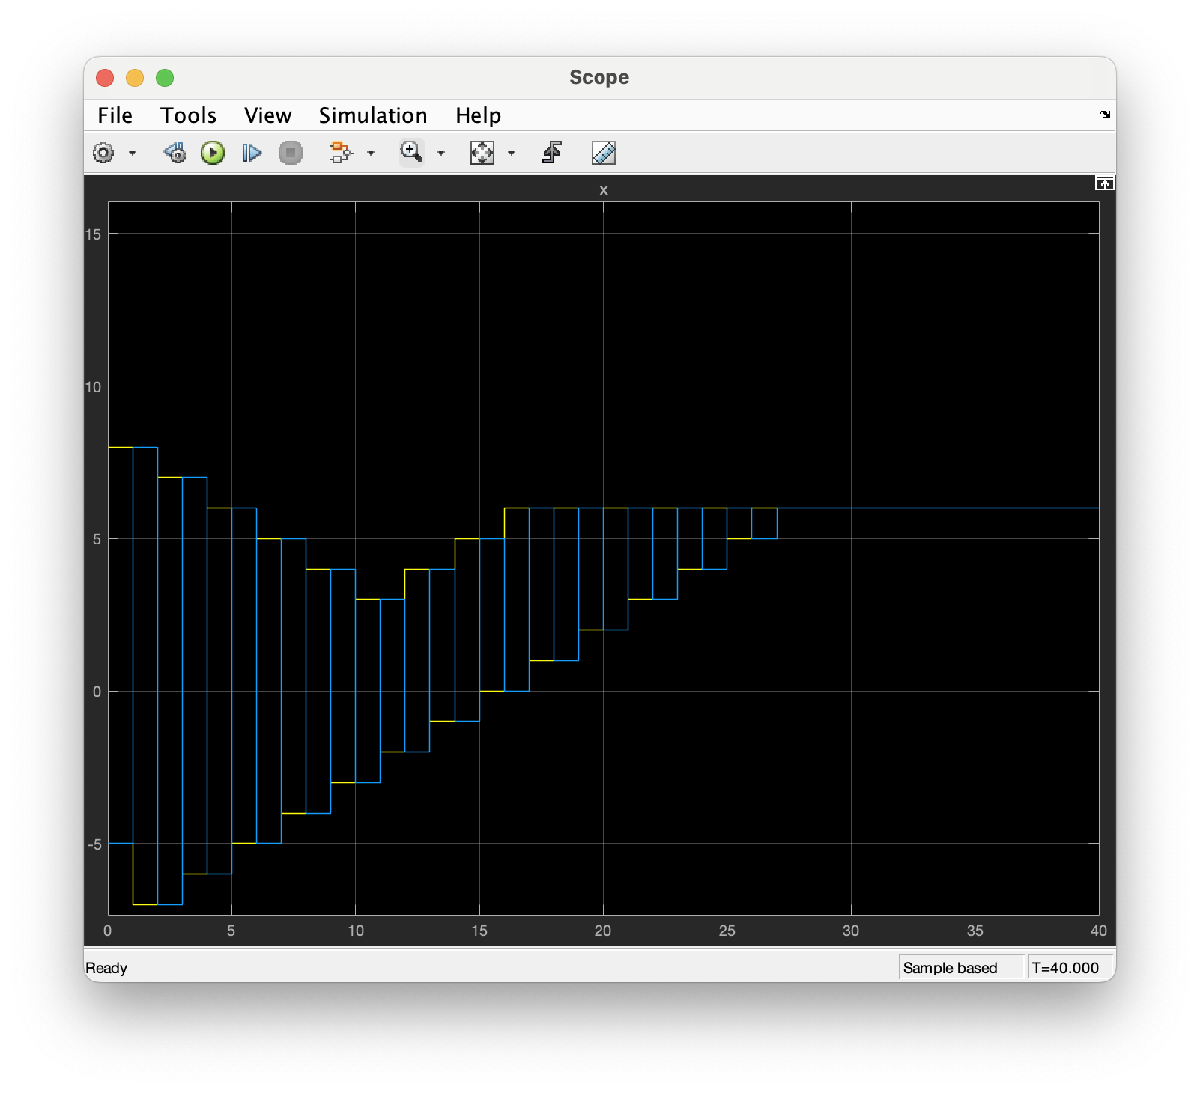

## Limites

Cependant dans cette implémentation la contrainte sur $u_k$ n'a pas été pris en compte, tel que définis plus haut j'ai eu des soucis à l'implementer